# Feature transformation

The process of modifying the original dataset to create new features that capture the variability and structures from the original data. Enhance model performance.

- Principal Component Analysis

- Factor Analysis

You an then reduce dimensionality while preserving as much information as possible.

Feature transformation methods need numeric data only.

% Script to fetch and combine closing prices for multiple stock indices with interpolation

% List of stock index symbols
symbols = {'^GSPC','^GSPTSE','^FCHI','^GDAXI','FTSEMIB.MI','^N225', '^FTSE','^HSI','IMOEX.ME'};


% Define the date range and parameters
startDate = '05-Mar-2013';
endDate = '30-May-2023';
interval = '1d';        % Daily data
fields = {'close'};     % Only closing prices

% Number of symbols
numSymbols = length(symbols);

% Cell arrays to store data
stockDataCell = cell(numSymbols, 1);
timetablesCell = cell(numSymbols, 1);

% Fetch data for each symbol and convert to timetable
for k = 1:numSymbols
    symbol = symbols{k};
    fprintf('Fetching data for %s...\n', symbol);
    
    try
        % Fetch data using the custom function
        stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields);
        
        % Remove time component and set dates to midnight
        stockData.Date = dateshift(stockData.Date, 'start', 'day');
        
        % Rename the 'Close' column to the symbol name
        varName = matlab.lang.makeValidName(symbol);
        stockData.Properties.VariableNames{'Close'} = varName;
        
        % Convert to timetable
        tt = table2timetable(stockData, 'RowTimes', 'Date');
        
        % Store the timetable
        timetablesCell{k} = tt(:, varName);  % Only include the price column
    catch ME
        warning('Failed to fetch data for %s: %s', symbol, ME.message);
        timetablesCell{k} = timetable();  % Empty timetable
    end
end

Fetching data for ^GSPC...
Fetching data for ^GSPTSE...
Fetching data for ^FCHI...
Fetching data for ^GDAXI...
Fetching data for FTSEMIB.MI...
Fetching data for ^N225...
Fetching data for ^FTSE...
Fetching data for ^HSI...
Fetching data for IMOEX.ME...



% Remove empty timetables
nonEmpty = ~cellfun(@isempty, timetablesCell);
timetablesCell = timetablesCell(nonEmpty);
symbols = symbols(nonEmpty);

% Collect all unique dates from all indices
allDates = [];
for k = 1:length(timetablesCell)
    allDates = [allDates; timetablesCell{k}.Date];
end

% Get unique sorted dates
commonDates = unique(allDates);

% Sort dates
commonDates = sort(commonDates);

% Resample all timetables to the common dates with interpolation
for k = 1:length(timetablesCell)
    % Synchronize to common dates with linear interpolation
    timetablesCell{k} = retime(timetablesCell{k}, commonDates, 'linear');
end

% Combine all timetables into one
combinedTimetable = timetablesCell{1};
for k = 2:length(timetablesCell)
    combinedTimetable = synchronize(combinedTimetable, timetablesCell{k}, 'union', 'linear');
end

% Convert timetable to table
combinedData = timetable2table(combinedTimetable);

% Rename the time variable to 'Date'
combinedData.Properties.VariableNames{1} = 'Date';

% Display the first few rows
disp('Combined Data (First 10 Rows):');

Combined Data (First 10 Rows):


disp(head(combinedData, 10));

       Date        x_GSPC    x_GSPTSE    x_FCHI    x_GDAXI    FTSEMIB_MI    x_N225    x_FTSE    x_HSI    IMOEX_ME
    ___________    ______    ________    ______    _______    __________    ______    ______    _____    ________

    05-Mar-2013    1539.8     12736      3787.2    7870.3       15974       11683       6432    22560     1486.4 
    06-Mar-2013    1541.5     12832      3773.8    7919.3       15900       11932     6427.6    22778     1491.5 
    07-Mar-2013    1544.3     12826      3793.8    7939.8       15947       11968     6439.2    22771     1491.3 
    08-Mar-2013    1551.2     12836      3840.1    7986.5       16204       12284     648


% Write the combined data to an Excel file
writetable(combinedData, 'Data.xlsx');
fprintf('Data with interpolated missing values has been written to StockIndicesData_Interpolated.xlsx\n');

Data with interpolated missing values has been written to StockIndicesData_Interpolated.xlsx


Compute returns

ret=diff(log(combinedData(:,2:end)))

ret = 2663×9 table
      x_GSPC        x_GSPTSE        x_FCHI        x_GDAXI      FTSEMIB_MI      x_N225        x_FTSE         x_HSI        IMOEX_ME  
    ___________    ___________    __________    ___________    __________    __________    __________    ___________    ___________

      0.0010839      0.0075094    -0.0035524      0.0062092    -0.0046433      0.021073    -0.0006843      0.0095875       0.003405
      0.0018148    -0.00042871      0.005291      0.0025777     0.0029516     0.0029967     0.0018031    -0.00028103     -9.388e-05
      0.0044711     0.00070919      0.012149      0.0058646      0.015987      0.026024     0.0068716       0.013977      0.0024411
      0.003243


ret=table2array(ret)

ret =     0.0011    0.0075   -0.0036    0.0062   -0.0046    0.0211   -0.0007    0.0096    0.0034
    0.0018   -0.0004    0.0053    0.0026    0.0030    0.0030    0.0018   -0.0003   -0.0001
    0.0045    0.0007    0.0121    0.0059    0.0160    0.0260    0.0069    0.0140    0.0024
    0.0032    0.0018   -0.0010   -0.0003   -0.0069    0.0053    0.0031   -0.0000    0.0073
   -0.0024    0.0016    0.0010   -0.0023   -0.0042   -0.0028    0.0011   -0.0087   -0.0041
    0.0013   -0.0105   -0.0010    0.0006   -0.0176   -0.0061   -0.0045   -0.0147   -0.0026
    0.0056    0.0044    0.0092    0.0109    0.0242    0.0115    0.0074    0.0028    0.0044
   -0.0016    0.0023   -0.0071   -0.0019   -0.0043    0.0144   -0.0061   -0.0038   -0.0040
   -0.0055   -0.0038   -0.0048   -0.0040   -0.0086   -0.0275   -0.0049   -0.0202   -0.0230
   -0.0024   -0.0006   -0.0131   -0.0079   -0.0160    0.0201   -0.0026   -0.0019   -0.0118
    0.0067    0.0041    0.0142    0.0068    0.0218    0.0067   -0.0013    0.0097    

To perform feature transformation, one need to normalize the data so that all variables have the same mean and standard deviation. 

That's because methods that rely on distance or covariance (like PCA) can be dominated by features with large numeric ranges unless you scale them.

One can normalize your data using the `zscore` function.



[retZ, muR, sdR] = zscore(ret);   % retZ is standardized returns

.

PCA is essentially a transformation of the data into the **space spanned by the eigenvectors of its covariance (or correlation) matrix**.

# Principal Component Analysis

Principal component analysis (PCA) transforms an *n*-dimensional feature space into a new *n*-dimensional space of orthogonal components. The components are ordered by the variation explained in the data.

[pcs, scrs, ~, ~, pctExp] = pca(retZ, ...
    'Algorithm','eig', ...        % eigen-decomposition (appropriate here)
    'Centered', true, ...         % retZ already centered; true is fine
    'NumComponents', size(retZ,2) ...
);


% Compute eigenvalues (variances explained by each component)
lambda = var(scrs, 0, 1)';  % column vector


The `pca` function transforms data into its principal components. The transformed data are pcs.

The second and fifth outputs, here scrs and `pctExp`, are the transformed data and the percent variance explained by each principal component.

One can name other outputs to return additional information about the transformation or use `~` to skip these outputs. For more information, see the [`pca`](https://www.mathworks.com/help/stats/pca.html) documentation.

The transformed data `scrs` and the percentage variance explained `pexp` are ordered in descending order according to the percentage variance explained.

pcs - Principal components coefficients. The contribution of each predictor to the *n* principal components.

(*n*-by-*n* matrix)

scrs - Principal component scores. The representations of the *m* observations in `X` in the principal component space.

(*m*-by-*n* matrix)

pctExp - Percent of the variance in the data explained by each principal component.

(1-by-*n* vector)

The transformed variables contain the same amount of information as the original data. However, assuming that the data contains some amount of noise, the components that contain the last few percent of explained variance are likely to represent noise more than information.

(Equivalent) PCA by diagonalizing Pearson correlation

%  -----------------------------

R = corrcoef(ret, 'Rows','pairwise');    % Pearson correlation of raw returns

R = (R + R')/2;                          % symmetrize for numerical stability

[Vec, Lam] = eig(R);

[lambda, ord] = sort(diag(Lam), 'descend');

V = Vec(:, ord);                         % eigenvectors (loadings)

pcs_R   = V;                             

pctExp_R = lambda / sum(lambda) * 100;   % same as pctExp (percent)

D) DIAGNOSTICS & PLOTS

You can use the `pareto`** function** (explained variance) to visualize the variance explained by the principle components.

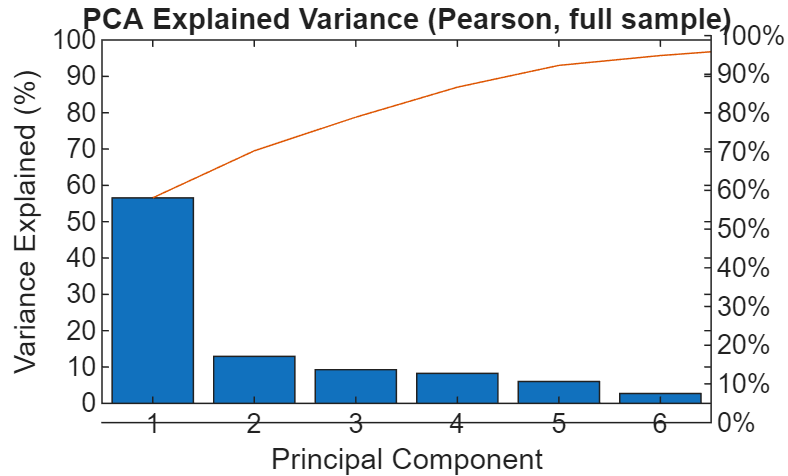

figure; pareto(pctExp);
title('PCA Explained Variance (Pearson, full sample)');...
    xlabel('Principal Component'); ylabel('Variance Explained (%)');

A Pareto function describes a situation where a small number of causes explain a large part of the effect — often called the 80/20 rule.

For example:

20% of customers might generate 80% of sales.

20% of bugs might cause 80% of software crashes.

Mathematically, the Pareto function (or Pareto distribution) models this type of imbalance.

It's a power-law distribution where large values are rare but have a big impact.

Its probability density function (PDF) is given by:


$$\[
f(x) = 
\begin{cases}
\frac{\alpha x_m^{\alpha}}{x^{\alpha + 1}}, & x \ge x_m, \\[10pt]
0, & x < x_m,
\end{cases}
\]$$


where:

- $$x_m > 0$$ is the scale parameter (the minimum possible value),

-    $ $\alpha > 0$$ is the shape parameter, which determines the heaviness of the tail.

You can use the `cumsum` and `find` functions to calculate the cumulative sum and find the first element that is greater than a threshold.

% Cumulative variance and k for thresholds (e.g., 90% and 95%)
cumExp = cumsum(pctExp);
k90 = find(cumExp >= 90, 1);
k95 = find(cumExp >= 95, 1);
fprintf('k (>=90%%): %d   |  k (>=95%%): %d\n', k90, k95);

k (>=90%): 5   |  k (>=95%): 6


Scree plot

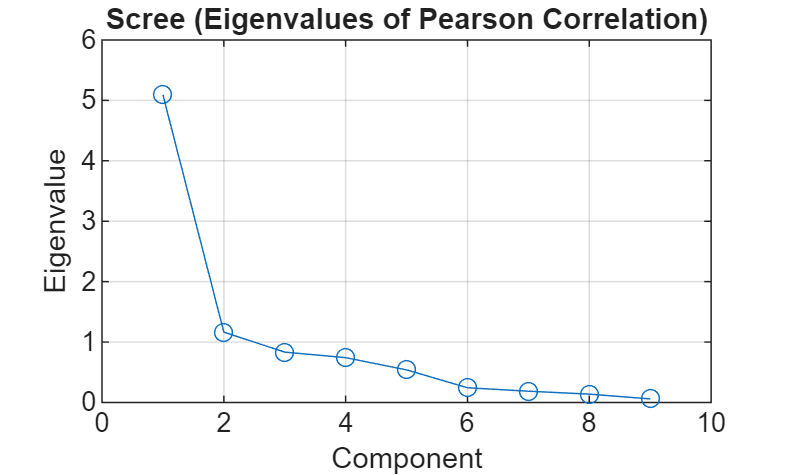

figure; plot(lambda, 'o-'); grid on;
title('Scree (Eigenvalues of Pearson Correlation)');...
    xlabel('Component'); ylabel('Eigenvalue');

Loadings heatmap for first few PCs (e.g., first 3)

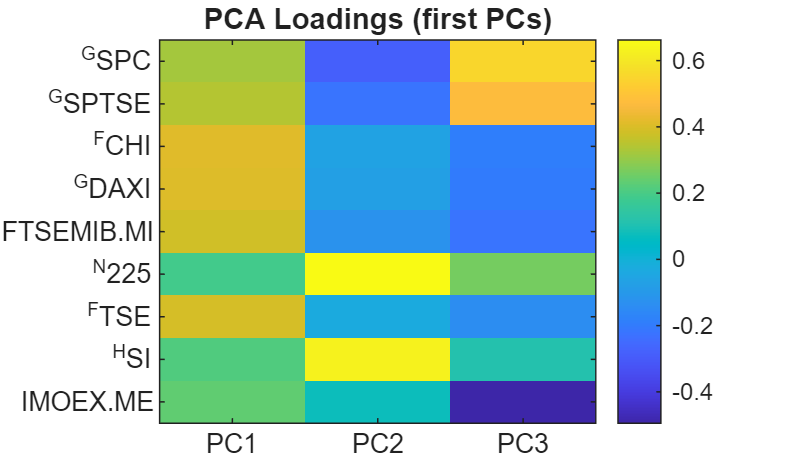

varNames=symbols;

kShow = min(3, size(pcs,2));
figure; imagesc(pcs(:,1:kShow)); colorbar;
set(gca,'XTick',1:kShow); xticklabels(compose('PC%d',1:kShow));
set(gca,'YTick',1:numel(varNames), 'YTickLabel', varNames);
title('PCA Loadings (first PCs)');

Biplot for first two PCs (optional, interpret which assets drive PC1/PC2)

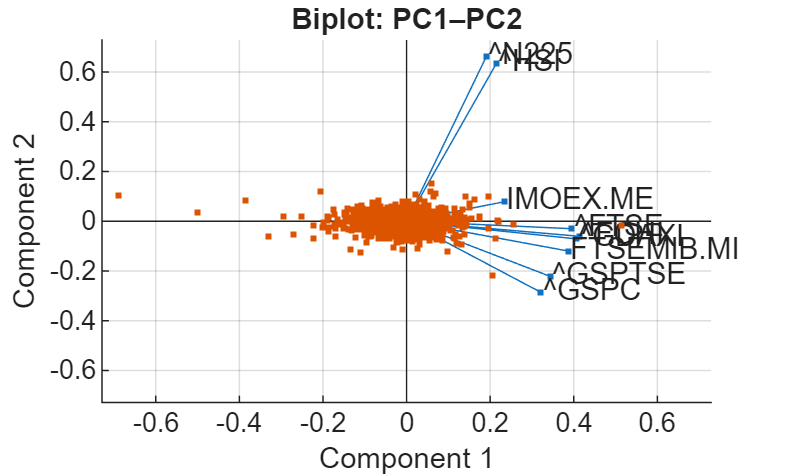

figure; biplot(pcs(:,1:2), 'Scores', scrs(:,1:2), 'VarLabels', varNames);
title('Biplot: PC1–PC2');

 SELECT k COMPONENTS & FORM TRANSFORMED DATA

k = k95;                        % for example, keep enough for 95% variance
PCA_scores   = scrs(:,1:k);     % transformed predictors (PC time series)
PCA_loadings = pcs(:,1:k);      % loadings (assets -> PCs)

 If you want "PCA features" per date in a table:

PCA_tbl = [ table(combinedData.Date(2:end), 'VariableNames', {'Date'}) , ...
            array2table(PCA_scores, 'VariableNames', compose('PC%d',1:k)) ];


QUICK INTERPRETATION HELPERS

Market mode strength (PC1 share)

pc1_share = pctExp(1);
fprintf('PC1 share of variance: %.2f%%\n', pc1_share);

PC1 share of variance: 56.57%


Contribution of each asset to PC1 (loading magnitudes)

[~, topIdx] = sort(abs(pcs(:,1)), 'descend');
disp('Top contributors to PC1 (by absolute loading):');

Top contributors to PC1 (by absolute loading):


disp(varNames(topIdx(1:min(5,end))));

    {'^FCHI'}    {'^GDAXI'}    {'^FTSE'}    {'FTSEMIB.MI'}    {'^GSPTSE'}



 Reconstruct correlation using first k PCs (sanity check)

Rk = pcs(:,1:k) * diag(lambda(1:k)) * pcs(:,1:k)';   % if you used eig on R
% Or, from pca() route, approximate covariance with kept components:
% covApprox = pcs(:,1:k) * diag(var(scrs(:,1:k))) * pcs(:,1:k)';  % since retZ has unit variances

The Pareto and scree analyses indicate that the first principal component accounts for 56.6 % of total return variance, confirming a single dominant global market mode.

The steep spectral decay (Figure X) suggests a highly integrated system, while the heatmap and biplot (Figures Y–Z) reveal regional clusters — Europe and North America forming the core, Asia and Russia representing orthogonal directions.

## Principal Component Analysis as an Eigenvector Transformation

Let $$\mathbf{X} \in \mathbb{R}^{n \times p}$$ be a data matrix with $$n$$ observations and $$p$$ variables. 

Each row of $$\mathbf{X}$$ represents an observation, and each column a variable.

1. Data centering and standardization

First, center the data by subtracting the mean of each variable:


$$\[
\mathbf{X}_c = \mathbf{X} - \mathbf{1}_n \mu^\top,
\]$$


where $$\mu$$ is the vector of column means and $$\mathbf{1}_n$$ is an $n
$-dimensional column vector of ones.

Optionally, standardize each column to have unit variance using the $z$-score:


$$\[
\mathbf{Z} = \frac{\mathbf{X}_c}\sigma},
\]$$


so that each variable has mean 0 and standard deviation 1.

2. Covariance matrix

Compute the empirical covariance matrix:


$$\[
\Sigma = \frac{1}{n-1}\mathbf{X}_c^\top \mathbf{X}_c.
\]$$


If the data were standardized, $$\Sigma$$ becomes the correlation matrix.

3. Eigen-decomposition

Solve the eigenvalue problem:


$$\[
\Sigma \mathbf{v}_i = \lambda_i \mathbf{v}_i,
\]$$


where $$\mathbf{v}_i$$ is the $$i$$-th eigenvector and $$\lambda_i$$ the corresponding eigenvalue.

The eigenvectors  $$\mathbf{v}_i$$ form an orthonormal basis for the feature space, and the eigenvalues represent the variance explained by each principal direction.

4. Transformation to principal component space

Arrange the eigenvectors in descending order of their eigenvalues:


$$\[
\mathbf{V} = [\,\mathbf{v}_1, \mathbf{v}_2, \dots, \mathbf{v}_p\,],
\qquad 
\lambda_1 \ge \lambda_2 \ge \dots \ge \lambda_p.
\]$$


The projection of the centered data onto this new orthogonal basis is:


$$\[
\mathbf{Y} = \mathbf{X}_c \mathbf{V}.
\]$$


Each column of $$\mathbf{Y}$ $corresponds to a \emph{principal component}, and the data have now been expressed in the \emph{principal component space}, whose axes are given by the eigenvectors of the covariance matrix.

5. Geometric interpretation

PCA can thus be interpreted as a rotation of the coordinate system  in the feature space:

- The first principal component $$\mathbf{v}_1$$ points in the direction of maximum variance.     It represents the axis along which the observations are most spread out, capturing the dominant pattern of co-movement across all variables.

-     The second component $$\mathbf{v}_2$$ is orthogonal to  $$\mathbf{v}_1$$and and captures the largest remaining variance not explained by the first component. It describes the next most significant, linearly independent mode of variability in the system.

- Each subsequent component $\mathbf{v}_i$$ ($$i = 3, \ldots, p$$) is orthogonal to all preceding ones and accounts for progressively smaller portions of the total variance.

#### Geometrically, this transformation corresponds to a rotation and re-scaling of the original coordinate axes so that the new axes (the principal components) align with the directions of maximum spread in the data cloud. 

In financial terms, the first principal component corresponds to the** global market mode,** capturing synchronized movements among all indices, while higher-order components describe \textbf{regional or idiosyncratic deviations} orthogonal to that global trend.